## 5.3. Import TensorFlow model into MATLAB

To illustrate the [TensorFlow & ONNX import/export capabilities](https://blogs.mathworks.com/deep-learning/2022/03/18/importing-models-from-tensorflow-pytorch-and-onnx/), we will take a workflow around an autonomous driving use case. 

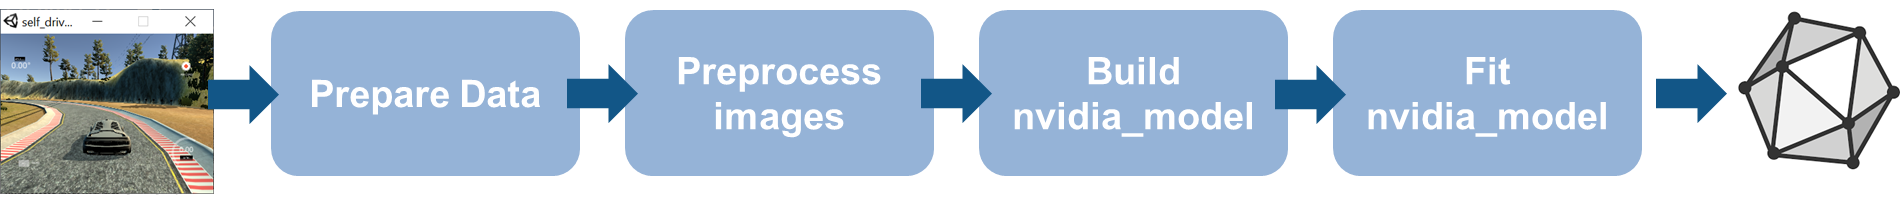

The data is generated by a simple [open-source driving simulator](https://github.com/udacity/self-driving-car-sim) from Udacity. 

And the model comes from a real-life experiment from NVIDIA about [End-to-end learning for self-driving cars](https://arxiv.org/pdf/1604.07316.pdf).

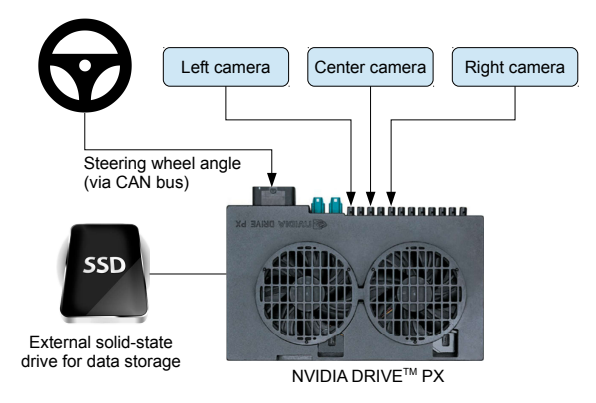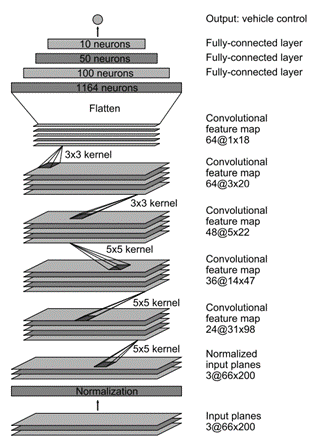

The inputs of the neural network are images from the camera and the output to predict in the steering angle (between -1 and 1). 

We will simplify the problem with only 5 classes(from left to right). 

*(optional) *Set up the parallel pool to use 4 workers for training on CPU

p = gcp('nocreate'); % If no pool, do not create new one.
if isempty(p)
   parpool()
else
    poolsize = p.NumWorkers
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 4
                 Busy: false
              Cluster: Processes (Local Cluster)
        AttachedFiles: {}
    AutoAddClientPath: true
            FileStore: [1x1 parallel.FileStore]
           ValueStore: [1x1 parallel.ValueStore]
          IdleTimeout: 30 minutes (30 minutes remaining)
          SpmdEnabled: true



Import csv file created by the Udacity simulator with the images locations and the steering ground truth.

filename = "driving_log.csv";
drivinglog = import_driving_log( filename );
drivinglog = drivinglog(2:end,:)

drivinglog = 7935×8 table
    VarName1                   center                                  left                                  right                   steering    throttle    reverse      speed   
    ________    ____________________________________    __________________________________    ___________________________________    ________    ________    _______    __________

        0       "center_2021_04_25_11_32_45_622.jpg"    "left_2021_04_25_11_32_45_622.jpg"    "right_2021_04_25_11_32_45_622.jpg"         0            0        0       4.4619e-06
        1       "center_2021_04_25_11_32_45_689.jpg"    "left_2021_04_25_11_32_45_689.jpg"    "right_2021_04_25_11_32_45_689.jpg"         0            0        0   

**Prepare data**

Analyse the range of values for the steering angle to find the optimal class values. 

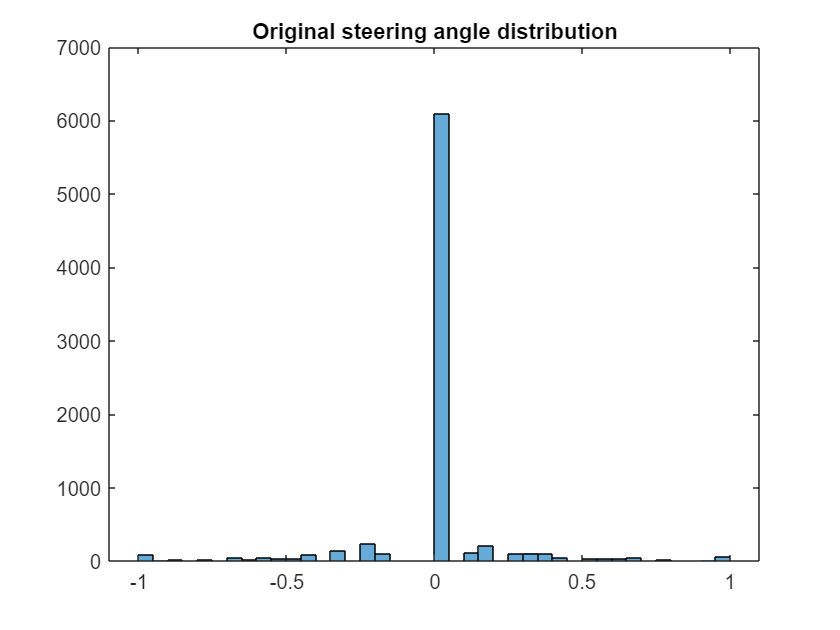

figure;
histogram(drivinglog.steering);
title("Original steering angle distribution");

Use discretize to group the steering angles into discrete bins.

steeringLimits = [-1 -0.5 -0.05 0 0.05 0.5 1];
steeringClasses = discretize(drivinglog.steering, steeringLimits, 'categorical');
classNames = categories(steeringClasses);

Merge the two bins that represent the angle close to 0 degrees. 

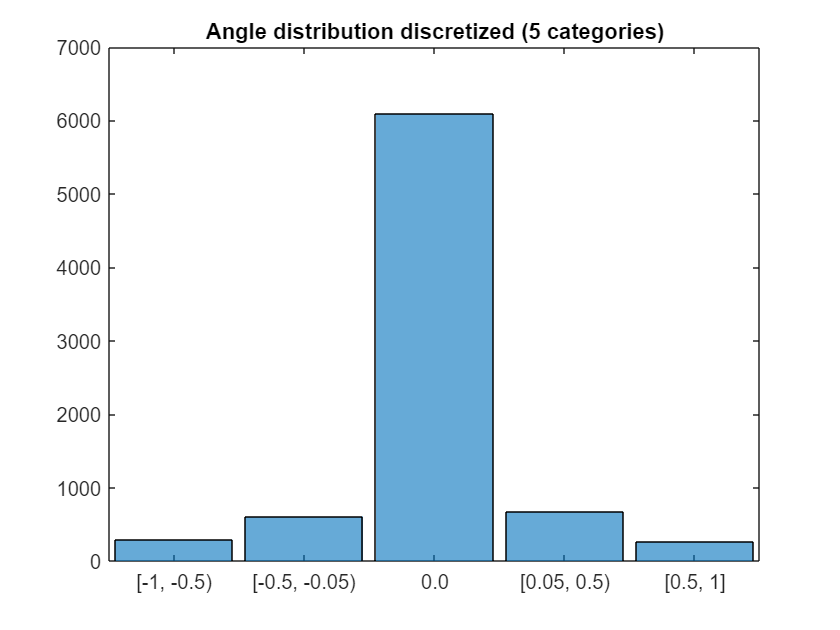

steeringClasses = mergecats(steeringClasses,["[-0.05, 0)","[0, 0.05)"], "0.0");
histogramClasses = histogram(steeringClasses);
title("Angle distribution discretized (5 categories)");

**Create image datastore and balance data (undersampling)**

The previous histogram shows that the dataset is highly unbalanced. Use countEachLabel to check how many instances there are of each class.

imds = imageDatastore("sim_data/"+drivinglog.center,"Labels", steeringClasses);
countEachLabel(imds)

ans = 5×2 table
        Label        Count
    _____________    _____

    [-1, -0.5)        288 
    [-0.5, -0.05)     611 
    0.0              6093 
    [0.05, 0.5)       679 
    [0.5, 1]          264 


Define how many samples of the unbalanced class should be kept and randomly select these samples. 

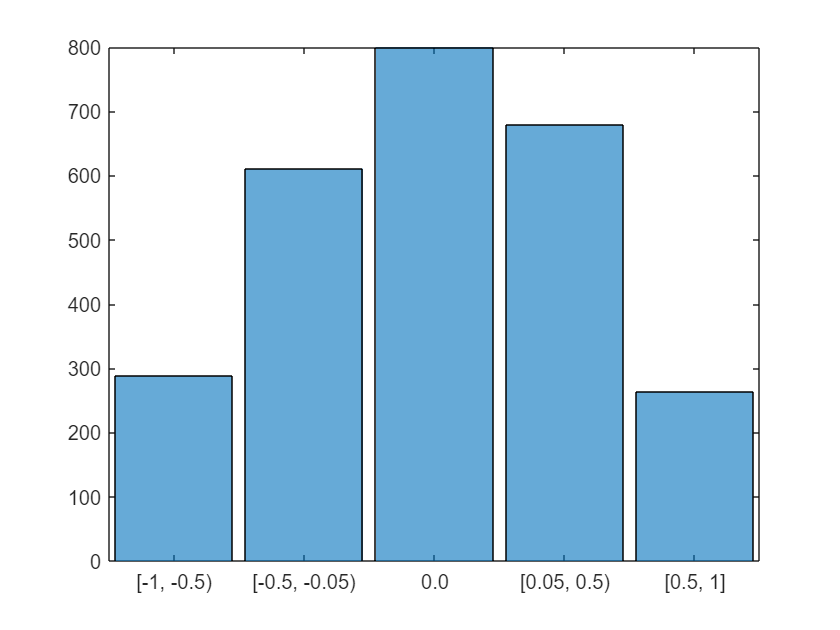

maxSamples = 800;
countLabel = countEachLabel(imds);
[~, unbalancedLabelIdx] = max(countLabel.Count);
unbalanced = imds.Labels == countLabel.Label(unbalancedLabelIdx);
idx = find(unbalanced);
randomIdx = randperm(numel(idx));
downsampled = idx(randomIdx(1:maxSamples));
retained = [find(~unbalanced) ; downsampled];
imds = subset(imds, retained');
histogram(imds.Labels)

**Separate the dataset into training, validation and testing**

Extract 90% of the data for training and the remaining for testing and validation. 

[imdsTrain, imdsValid,imdsTest] = splitEachLabel(imds, 0.9, 0.05, 0.05);

**Preprocess the images** by resizing it and converting it to the YCbCr color space. 

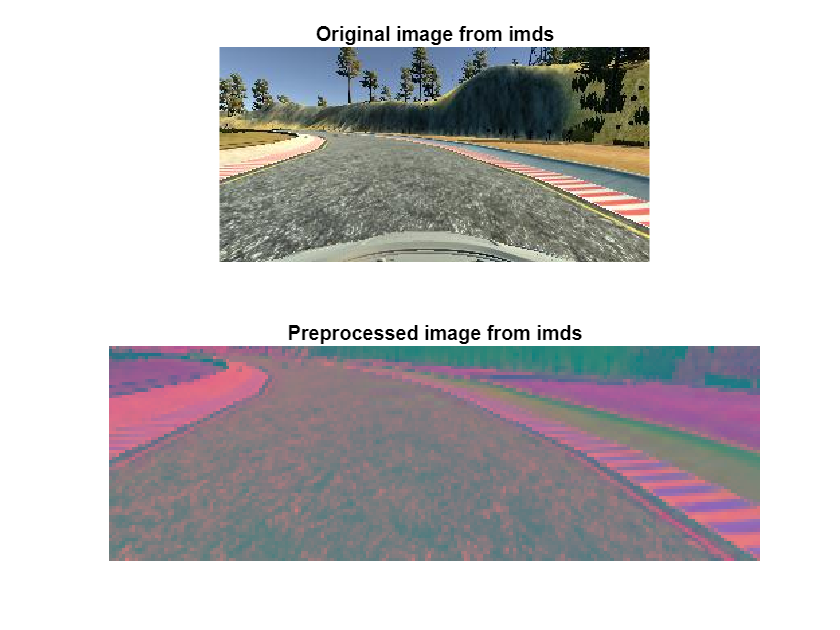

trainData = transform(imdsTrain, @imagePreprocess, "IncludeInfo", true);
testData = transform(imdsTest, @imagePreprocess, "IncludeInfo", true);
valData = transform(imdsValid, @imagePreprocess, "IncludeInfo", true);
imds_origI = imdsTrain.read;
imds_newI = trainData.read{1};
subplot(211), imshow(imds_origI), title("Original image from imds")
subplot(212), imshow(imds_newI), title("Preprocessed image from imds")

**Modify the model:**

Load the network from keras model and display with [Deep Network Designer](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html).

It is recommended to save and import the model in the SavedModel format instead of the [HDF5 format](http://www.tensorflow.org/tutorials/keras/save_and_load#save_the_entire_model) (you might get a warning). 

layers = importKerasLayers("tf_model.h5")

layers =   20×1 Layer array with layers:

     1   'conv2d_5_input'            Image Input         66×200×3 images
     2   'conv2d_5'                  2-D Convolution     24 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     3   'conv2d_5_elu'              ELU                 ELU with Alpha 1
     4   'conv2d_6'                  2-D Convolution     36 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     5   'conv2d_6_elu'              ELU                 ELU with Alpha 1
     6   'conv2d_7'                  2-D Convolution     48 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     7   'conv2d_7_elu'              ELU                 ELU with Alpha 1
     8   'conv2d_8'                  2-D Convolution     64 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     9   'conv2d_8_elu'              ELU                 ELU with Alpha 1
    10   'conv2d_9'         

deepNetworkDesigner(layers)

Remove the last layer used for regression and add the layers for a classification with 5 classes (then export net as **layers_1**)

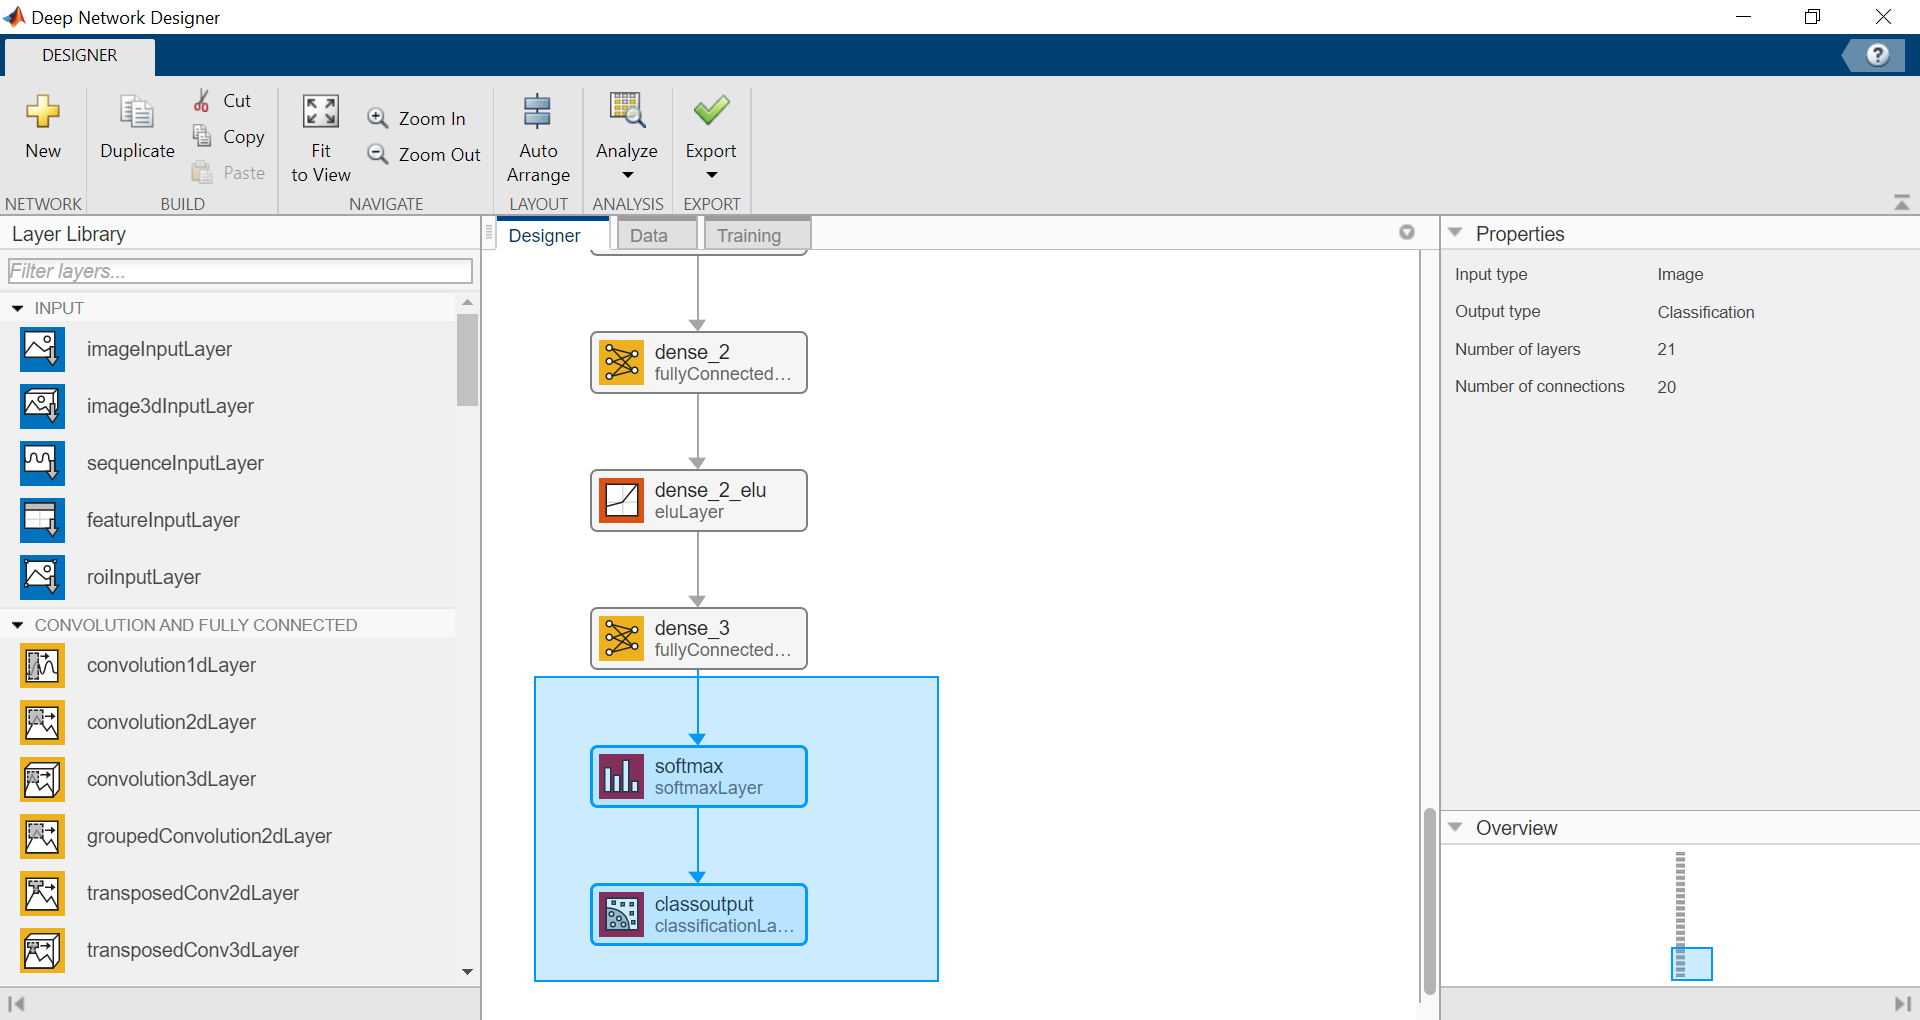

*(programmatic alternative) *Remove layers used for regression and add the layers for a classification with 5 classes

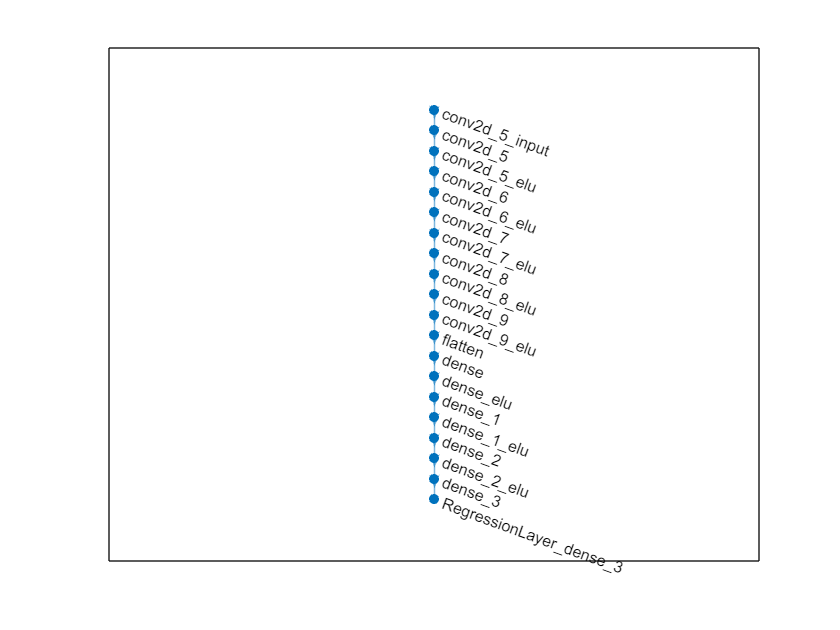

netGraph = layerGraph(layers);
clf; plot(netGraph)

classificationLayers = [fullyConnectedLayer(5,"Name","dense_3"), ...
                        softmaxLayer("Name","softmax"), ...
                        classificationLayer("Name","classoutput")];
netGraph = removeLayers(netGraph, {'dense_3', 'RegressionLayer_dense_3'});
netGraph = addLayers(netGraph,classificationLayers);
layers_1 = netGraph.Layers

layers_1 =   21×1 Layer array with layers:

     1   'conv2d_5_input'   Image Input             66×200×3 images
     2   'conv2d_5'         2-D Convolution         24 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     3   'conv2d_5_elu'     ELU                     ELU with Alpha 1
     4   'conv2d_6'         2-D Convolution         36 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     5   'conv2d_6_elu'     ELU                     ELU with Alpha 1
     6   'conv2d_7'         2-D Convolution         48 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     7   'conv2d_7_elu'     ELU                     ELU with Alpha 1
     8   'conv2d_8'         2-D Convolution         64 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     9   'conv2d_8_elu'     ELU                     ELU with Alpha 1
    10   'conv2d_9'         2-D Convolution         64 3×3 convolutions

**Train the model: **(I am using my CPU here, but I recommend to speed it up on a GPU)

Training across multiple CPUs.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


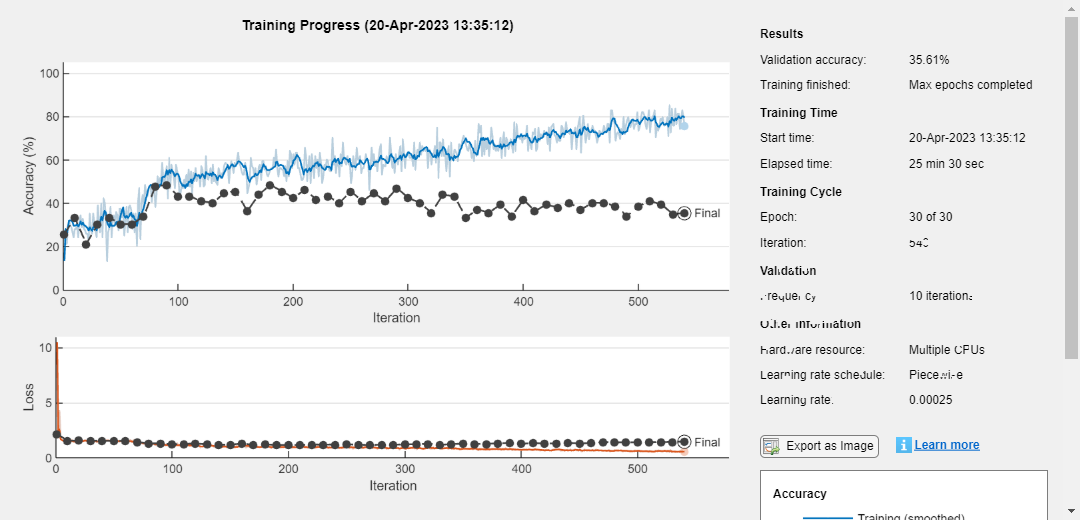

|       1 |           1 |       00:00:22 |       13.28% |       25.76% |      10.4919 |       2.1576 |          0.0010 |
|       1 |          10 |       00:00:58 |       28.12% |       33.33% |       1.5870 |       1.5280 |          0.0010 |
|       2 |          20 |       00:01:38 |       25.78% |       21.21% |       1.6118 |       1.5622 |          0.0010 |
|       2 |          30 |       00:02:07 |       39.06% |       30.30% |       1.4792 |       1.5493 |          0.0010 |
|       3 |          40 |       00:02:37 |       28.91% |       33.33% |       1.5287 |       1.5283 |          0.0010 |
|       3 |          50 |       00:03:08 |       37.50% |       30.30% |       1.4375 |       1.5323 |          0.0010 |
|       4 |          60 |       00:03:39 |       28.12% |       30.30% |       1.4746 |       1.5304 |          0.0010 |
|       4 |          70 |       00:04:07 |       38.28% |       34.09% |       1.3943 |       1.4132 |          0.0010 |
|       5 |          80 |       

initialLearnRate = 0.001;
maxEpochs = 30;
miniBatchSize = 100;

options = trainingOptions("adam", ...
    "MaxEpochs",maxEpochs, ...
    "InitialLearnRate",initialLearnRate, ...
    "Plots","training-progress",  ...
    "ValidationData",valData, ...
    "ValidationFrequency",10, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropPeriod",10, ...
    "LearnRateDropFactor",0.5, ...
    "ExecutionEnvironment","parallel",...
    "Shuffle","every-epoch");

net = trainNetwork(trainData, layers_1, options);

**Save model: **Save the new trained network in a MAT format. 

model_name = "net-class-30-1e-4-drop10-0_5"; % classification-epochs-learning_rate-drop_period-drop_factor
save(model_name+".mat","net") 

Export it to a ONNXNetwork format.

exportONNXNetwork(net,model_name+".onnx")

**Test model: **

Plot predicted and ground truth values for steering angle using the testing dataset. 

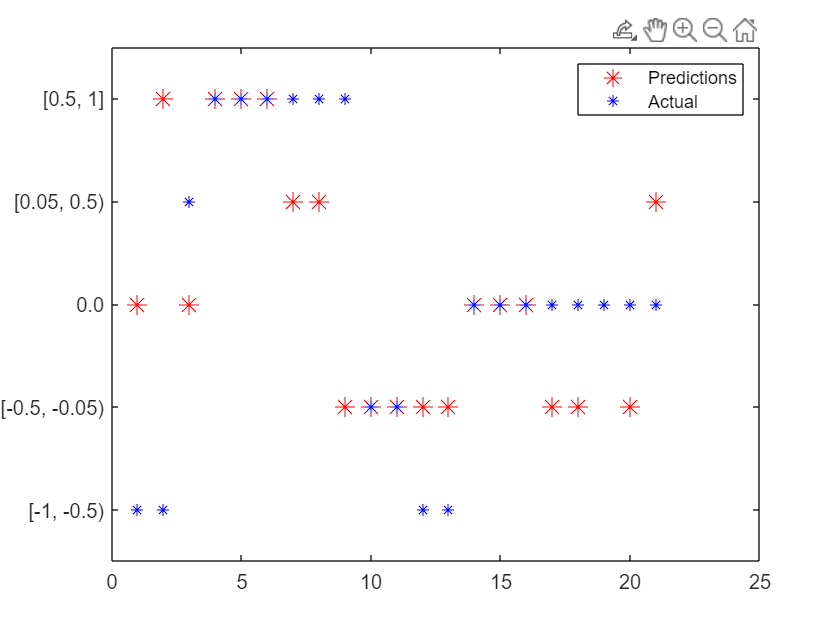

model_name = "net-class-30-1e-4-drop10-0_5"; % classification-epochs-learning_rate-drop_period-drop_factor
load(model_name+".mat","net")
predSteering = classify(net, testData);

figure
startTest = 80;
endTest = 100;
plot(predSteering(startTest:endTest), 'r*', "MarkerSize",10)
hold on
plot(imdsTest.Labels(startTest:endTest), 'b*')
legend("Predictions", "Actual")
hold off

Display the confusion matrix. 

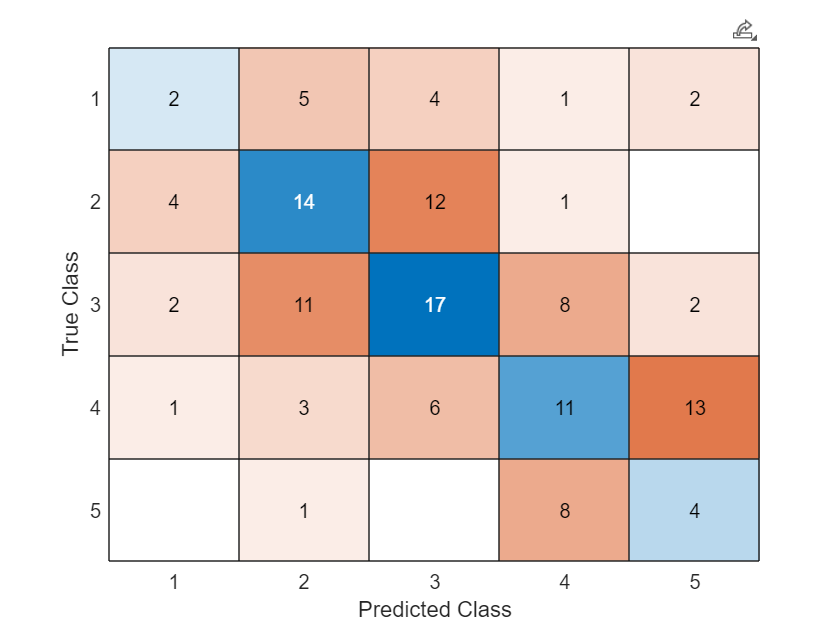

confMat = confusionmat(imdsTest.Labels, predSteering);
confusionchart(confMat)

Display the testing image and the predicted label along with the ground truth. 

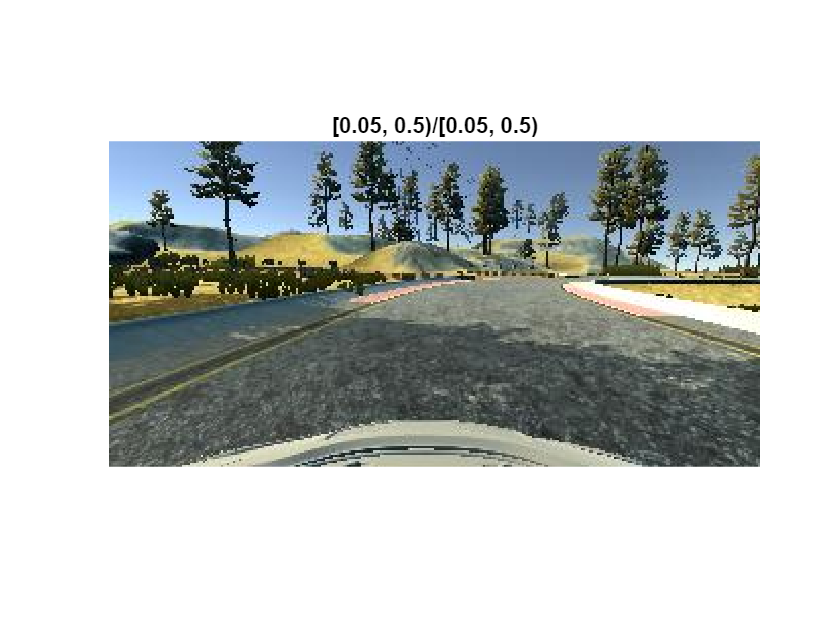

numberImages = length(imdsTest.Labels);
i = 42;
img = readimage(imdsTest, i);
imshow(img),title(char(imdsTest.Labels(i)) + "/" +char(predSteering(i)));

## Helper Functions

function drivinglog = import_driving_log(filename, dataLines)
%IMPORTFILE Import data from a text file
%  DRIVINGLOG = IMPORTFILE(FILENAME) reads data from text file FILENAME
%  for the default selection.  Returns the data as a table.
%
%  DRIVINGLOG = IMPORTFILE(FILE, DATALINES) reads data for the specified
%  row interval(s) of text file FILENAME. Specify DATALINES as a
%  positive scalar integer or a N-by-2 array of positive scalar integers
%  for dis-contiguous row intervals.
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 28-May-2021 21:31:34

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [1, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "center", "left", "right", "steering", "throttle", "reverse", "speed"];
opts.VariableTypes = ["double", "string", "string", "string", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["center", "left", "right"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["center", "left", "right"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["VarName1", "steering", "throttle", "reverse", "speed"], "ThousandsSeparator", ",");

% Import the data
drivinglog = readtable(filename, opts);

end

function [dataOut, info] = imagePreprocess(dataIn, info)

imgOut = dataIn(60:135, :, :);
imgOut = rgb2ycbcr(imgOut);
imgOut = imresize(imgOut, [66 200]);
dataOut = {imgOut, info.Label};

end